clear;
syms x y;

left= diff(y) + 3*y + 7*int(y);
right= diff(x) + 6*x;

L_left=laplace(left);
L_right=laplace(right);

Fdt=simplify(L_right/L_left)

$$Fdt = \frac{s\,\left(s+6\right)}{s^{2}+3\,s+7}$$


[n,d]=numden(simplify(L_right/L_left));


%a)

disp('ecuacion caracteristica: ')

ecuacion caracteristica: 


D=0

D = 0


disp('polinomio caracteristico: ')

polinomio caracteristico: 


D=d

$$D = s^{2}+3\,s+7$$


%polos
D=sym2poly(d);
polos=roots(D)

polos =   -1.5000 + 2.1794i
  -1.5000 - 2.1794i



%ceros
N=sym2poly(n);
ceros=roots(N)

ceros =      0
    -6


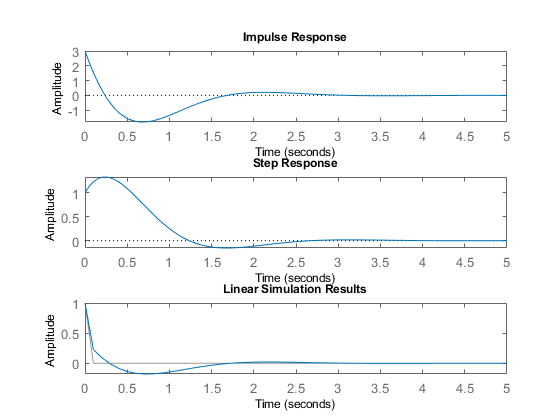



%b)
Tfinal=5; %segundos que dura la simulacion
FDT=tf(N,D);

%impulso
subplot(3,1,1)
impulse(FDT,Tfinal)

%escalon
subplot(3,1,2)
step(FDT,Tfinal)

%arbitraria
subplot(3,1,3)
t=0:.1:Tfinal;

rampa = [t];

impulso = dirac(t);
idx=impulso==Inf;
impulso(idx)=1; %cambiamos Inf por un 1

escalon = heaviside(t);

lsim(FDT,impulso,t);